# NRG: Impurity spectral function

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will compute the spectral functions by using the full density matrix NRG (fdmNRG) method. We consider the retarded Green's functions,


$$G[\hat{O}_1, \hat{O}_2^\dagger] (t) = -i \theta (t) \mathrm{Tr} \big( \hat{\rho} [ \hat{O}_1 (t), \hat{O}_2^\dagger ]_\pm ] \big) .$$
 

Note the second operator $\hat{O}_2^\dagger$ is Hermtian-conjugated. The spectral functions are given by the imaginary parts of the Green's functions in the frequency domain,


$$A[\hat{O}_1, \hat{O}_2^\dagger] (\omega) = \frac{-1}{\pi} \mathrm{Im} \int_{-\infty}^{+\infty} \mathrm{d}t \, e^{\mathrm{i} \omega t} \, G[\hat{O}_1, \hat{O}_2^\dagger] (t).$$


The fdmNRG method evaluates the Lehmann representation for the spectral functions with using the Anders–Schiller basis states as the energy eigenstates.

## Exercise (a): Complete the function for fdmNRG

There is a function `getAdisc_Ex.m`, which is in the same sub-directory with this script. This function takes the input of `O1` and `O2` that represent $\hat{O}_1$ and $\hat{O}_2$ (without Hermitian conjugation), respectively. Then it generates a discrete spectral function that is the collection of Dirac $\delta$ functions multiplied with spectral weights. Each spectral weight is given by the product of matrix elements of the local operators (`O1` and `O2`) and the full density matrix (generated by running `NRG/getRhoFDM.m` in advance).

The results `odisc` and `Adisc` define the histogram for the discrete spectral function; `Adisc(n)` is the sum of the spectral weights lumped into a histogram bin whose center position is `odisc(n)`. These results are fed as the input to `NRG/getAcont.m`, which broadens a discrete spectral function logarithmically to obtain a continuous curve for the spectral function, following the recipe given in Lee2016 [[S.-S. B. Lee and A. Weichselbaum, Phys. Rev. B **94**, 235127 (2016)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.94.235127)]. Interested readers can refer to Lee2016 for details.

Complete the parts of `getAdisc_Ex.m`, enclosed by the comments `TODO (start)` and `TODO (end)`.

We can verify the implementation of `getAdisc_Ex.m` by running the following script. We take the same single-impurity Anderson model (SIAM) and the NRG-related parameters (except for larger chain length `N`) used in the previous tutorial.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 60; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ozin,RhoV2in,Lambda,N);

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% iterative diagonalization
Inrg = NRG_IterDiag(H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-25 16:21:05 | NRG: start
22-10-25 16:21:05 | #00/60 : NK=4/4, EK=0/0
22-10-25 16:21:05 | #01/60 : NK=16/16, EK=0.04878/0.04878
22-10-25 16:21:05 | #02/60 : NK=64/64, EK=3.207/3.207
22-10-25 16:21:05 | #03/60 : NK=256/256, EK=6.221/6.221
22-10-25 16:21:05 | #04/60 : NK=328/1024, EK=4.999/13.01
22-10-25 16:21:06 | #05/60 : NK=304/1312, EK=4.681/9.125
22-10-25 16:21:06 | #06/60 : NK=328/1216, EK=5.009/10.56
22-10-25 16:21:06 | #07/60 : NK=304/1312, EK=4.741/9.182
22-10-25 16:21:06 | #08/60 : NK=328/1216, EK=5.038/10.6
22-10-25 16:21:07 | #09/60 : NK=304/1312, EK=4.852/9.268
22-10-25 16:21:07 | #10/60 : NK=328/1216, EK=5.109/10.7
22-10-25 16:21:07 | #11/60 : NK=304/1312, EK=5.048/9.432
22-10-25 16:21:07 | #12/60 : NK=328/1216, EK=5.265/10.92
22-10-25 16:21:08 | #13/60 : NK=300/1312, EK=5.305/9.782
22-10-25 16:21:08 | #14/60 : NK=328/1200, EK=5.554/11.22
22-10-25 16:21:08 | #15/60 : NK=320/1312, EK=5.712/10.54
22-10-25 16:21:08 | #16/60 : NK=306/1280, EK=5.863/11.25
22-10-25 16:21:09 

The Kondo temperature $T_\mathrm{K}$ of this system is:

TK = 0.4107*sqrt(U*Delta0/2)*exp(-pi*U/8/Delta0 + pi*Delta0/2/U);
disp(TK);

   5.9827e-07



Let's consider a temperature $T$ sufficiently smaller than $T_\mathrm{K}$. Then we construct the full density matrix by running `NRG/getRhoFDM.m`.

T = 1e-10;
Inrg = getRhoFDM(Inrg,T);

22-10-25 16:21:19 | Construct full density matrix @ T = 1e-10.
Elapsed time: 1.636s, CPU time: 11.83s, Avg # of cores: 7.232


Compute the discrete spectral function for the impurity Green's function with $\hat{O}_1 = \hat{O}_2 = \hat{d}_{\sigma}$.

[odisc,Adisc1] = getAdisc_Ex (Inrg,F(:,:,1),F(:,:,1),Z); % for spin-up

22-10-25 16:21:20 | Correlation function for anti-commuting operators.
22-10-25 16:21:21 | #00/60 : sum(Adisc) = 0
22-10-25 16:21:21 | #01/60 : sum(Adisc) = 0
22-10-25 16:21:21 | #02/60 : sum(Adisc) = 0
22-10-25 16:21:21 | #03/60 : sum(Adisc) = 0
22-10-25 16:21:21 | #04/60 : sum(Adisc) = 9.542e-08
22-10-25 16:21:21 | #05/60 : sum(Adisc) = 7.235e-06
22-10-25 16:21:21 | #06/60 : sum(Adisc) = 0.0002238
22-10-25 16:21:21 | #07/60 : sum(Adisc) = 0.0002424
22-10-25 16:21:21 | #08/60 : sum(Adisc) = 0.0007828
22-10-25 16:21:21 | #09/60 : sum(Adisc) = 0.0008294
22-10-25 16:21:22 | #10/60 : sum(Adisc) = 0.002181
22-10-25 16:21:22 | #11/60 : sum(Adisc) = 0.002298
22-10-25 16:21:22 | #12/60 : sum(Adisc) = 0.005701
22-10-25 16:21:22 | #13/60 : sum(Adisc) = 0.006005
22-10-25 16:21:22 | #14/60 : sum(Adisc) = 0.01495
22-10-25 16:21:22 | #15/60 : sum(Adisc) = 0.01555
22-10-25 16:21:23 | #16/60 : sum(Adisc) = 0.04585
22-10-25 16:21:23 | #17/60 : sum(Adisc) = 0.05451
22-10-25 16:21:23 | #18/60 : sum(Adis

[~    ,Adisc2] = getAdisc_Ex (Inrg,F(:,:,2),F(:,:,2),Z); % for spin-down

22-10-25 16:21:30 | Correlation function for anti-commuting operators.
22-10-25 16:21:30 | #00/60 : sum(Adisc) = 0
22-10-25 16:21:30 | #01/60 : sum(Adisc) = 0
22-10-25 16:21:30 | #02/60 : sum(Adisc) = 0
22-10-25 16:21:30 | #03/60 : sum(Adisc) = 0
22-10-25 16:21:30 | #04/60 : sum(Adisc) = 9.542e-08
22-10-25 16:21:30 | #05/60 : sum(Adisc) = 7.235e-06
22-10-25 16:21:30 | #06/60 : sum(Adisc) = 0.0002238
22-10-25 16:21:30 | #07/60 : sum(Adisc) = 0.0002424
22-10-25 16:21:30 | #08/60 : sum(Adisc) = 0.0007828
22-10-25 16:21:30 | #09/60 : sum(Adisc) = 0.0008294
22-10-25 16:21:31 | #10/60 : sum(Adisc) = 0.002181
22-10-25 16:21:31 | #11/60 : sum(Adisc) = 0.002298
22-10-25 16:21:31 | #12/60 : sum(Adisc) = 0.005701
22-10-25 16:21:31 | #13/60 : sum(Adisc) = 0.006005
22-10-25 16:21:31 | #14/60 : sum(Adisc) = 0.01495
22-10-25 16:21:31 | #15/60 : sum(Adisc) = 0.01555
22-10-25 16:21:32 | #16/60 : sum(Adisc) = 0.04585
22-10-25 16:21:32 | #17/60 : sum(Adisc) = 0.05451
22-10-25 16:21:32 | #18/60 : sum(Adis

Let's first check the spectral sum rule.

disp([sum(Adisc1) sum(Adisc2)]-1);

   1.0e-14 *

   -0.2665   -0.3997



The sums are 1's, which is consistent with $\mathrm{Tr} ( \hat{\rho} [ \hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger ]_{+} ) = 1$.

Now we broaden the discrete spectral functions to obtain the continuous curves.

[ocont,Acont1] = getAcont(odisc,Adisc1,log(Lambda),T/5);
[~    ,Acont2] = getAcont(odisc,Adisc2,log(Lambda),T/5);

How do they look like?

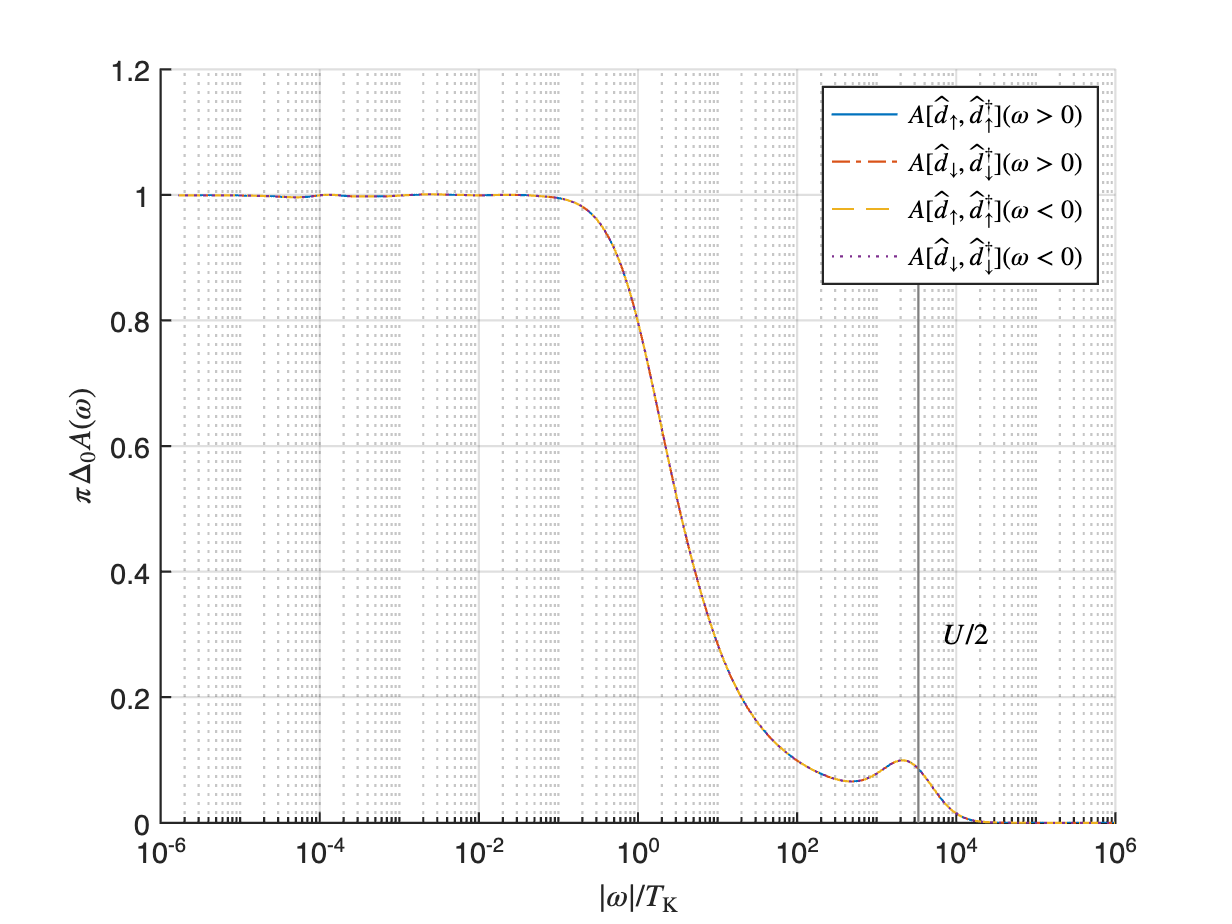

figure;
hold on;
% positive frequencies
plot(ocont(ocont>0)/TK,Acont1(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','-');
plot(ocont(ocont>0)/TK,Acont2(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','-.');
% negative frequencies
plot(-ocont(ocont<0)/TK,Acont1(ocont<0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','--');
plot(-ocont(ocont<0)/TK,Acont2(ocont<0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle',':');
% guide to the eye
plot(U/2/TK*[1 1],[0 1],'LineWidth',1,'LineStyle','-', ...
    'Color',[1 1 1]*0.5);
text(U/TK,0.3,'$U/2$','FontSize',13, ...
    'Interpreter','latex','HorizontalAlignment','left');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log');
legend({'$A[\hat{d}_{\uparrow},\hat{d}_{\uparrow}^\dagger] (\omega > 0)$', ...
    '$A[\hat{d}_{\downarrow},\hat{d}_{\downarrow}^\dagger] (\omega > 0)$', ...
    '$A[\hat{d}_{\uparrow},\hat{d}_{\uparrow}^\dagger] (\omega < 0)$', ...
    '$A[\hat{d}_{\downarrow},\hat{d}_{\downarrow}^\dagger] (\omega < 0)$' ...
    },'Interpreter','latex');
xlabel('$| \omega | / T_\mathrm{K}$','Interpreter','latex');
ylabel('$\pi \Delta_0 A(\omega)$','Interpreter','latex');
xlim([1e-6 1e6]);
grid on;

We observe several important features.

- The system has the spin symmetry (due to the absence of magnetic field) and the particle-hole symmetry. So all the curves lie on top of each other.

- There are side peaks at $\omega = \pm U/2$, as marked by vertical dash-dotted line. They come from local excitations from singly occupied states to the double occupied state for the peak at $\omega = U/2$ (to the empty state for the peak at $\omega = -U/2$).

- The full-width-half-maximum of the "Kondo peak" (peak centered at $\omega = 0$) is roughly $T_\mathrm{K}$.

- There is a plateau for $| \omega | \ll T_\mathrm{K}$ which corresponds to the top of the Kondo peak. The height of the Kondo peak satisfies the Friedel sum rule, $\pi \Delta_0 A (\omega = 0) = 1$, up to a few percent error. Note that the Friedel sum rule is the exact relation holds at $T = 0$.

The quality of the curve (e.g., frequency resolution) can be improved by using so-called $z$-averaging, that is, by mixing the NRG results with the logarithmic discretization grid relatively shifted with respect to each other.

Also, the accuracy with respect to the Friedel sum rule can be further improved by using more advanced logarithmic discretization schemes (see e.g., [[R. Zitko and Th. Pruschke, Phys. Rev. B **79**, 085106 (2009)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.79.085106)]) and by using the "self-energy trick" (see [[R. Bulla, A. C. Hewson, and Th. Pruschke, J. Phys.: Condens. Matter **10**, 8365 (1998)](https://iopscience.iop.org/article/10.1088/0953-8984/10/37/021/meta)]).

## Exercise (b): Temperature dependence of the impurity spectral function

Compute the impurity spectral function $A[\hat{d}_\sigma, \hat{d}_\sigma^\dagger] (\omega)$ for different temperatures. Discuss how the lineshapes change with temperatures.

## Exercise (c): Dynamical susceptibilities

In the previous tutorial, we computed the impurity contribution to the magnetic susceptibility. This property is static, i.e., does not depend on frequency $\omega$ (or energy, equivalently, by setting $\hbar = 1$). Some experimental probes such as neutron scattering can resolve the frequency dependence of the spin susceptibility. The frequency dependence encodes interesting information of the system.

In this exercise, we will consider the dynamical spin susceptibility at the impurity, which is the retarded-time correlation function of spin operators $\hat{S}_{d,z}$. That is, its spectral function, say $\chi''_s (\omega)$, is obtained by substituting $\hat{O}_1 = \hat{O}_2 = \hat{S}_{d,z}$ to the first equations at the top of this document.

Similarly, we also consider the dynamical charge susceptibility at the impurity, by choosing $\hat{O}_1 = \hat{O}_2 = \hat{n}_d - \langle \hat{n}_d \rangle$, where $\hat{n}_d = \hat{n}_{d\uparrow} + \hat{n}_{d\downarrow}$ counts the particles of both spins at the impurity. (**Quick exercise:** Why do we use $\hat{n}_d - \langle \hat{n}_d \rangle$, not $\hat{n}_d$?) We denote the spectral function of the charge susceptibility as $\chi''_c (\omega)$.

Compute $\chi''_s (\omega)$ and $\chi''_c (\omega)$ for the SIAM with the same choice of parameters as in the above demonstration of the impurity spectral function. How do the curves look like? Can you interpret the peak locations in the curves?